clear all; clc;

bag= rosbag('2018-07-07-16-58-09.bag');
DrivePointTopic= select(bag, 'Topic', '/drive_points');
DrivePointMsg = readMessages(DrivePointTopic,'DataFormat','struct');
path_x_all= cellfun(@(m) double(m.X),DrivePointMsg);
path_y_all= cellfun(@(m) double(m.Y),DrivePointMsg);

PointCloudTopic= select(bag, 'Topic', '/point_clouds');
PointCloudMsg= readMessages(PointCloudTopic);

SteerTopic= select(bag, 'Topic', '/cmd_steering_angle');
SteerMsg= readMessages(SteerTopic, 'DataFormat', "struct");
SteerAngle_org= cellfun(@(m) double(m.SteeringAngle), SteerMsg);

pc_list=[];
for i= 1:5:length(PointCloudMsg)
    pc_list= [pc_list; PointCloudMsg{i,1}.readXYZ];
end

index_NotNaN= find(~isnan(path_x_all));
path_x= path_x_all(index_NotNaN);
path_y= path_y_all(index_NotNaN);


i_NotNaN= find(~isnan(SteerAngle_org));
SteerAngle= SteerAngle_org(i_NotNaN);

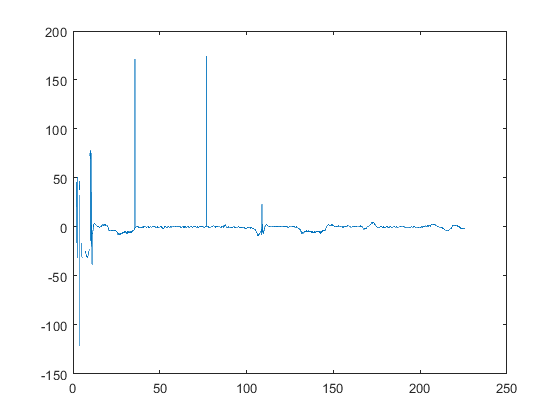

figure;
num= 1:1/100:length(SteerAngle_org)/100;
plot(num, SteerAngle_org(1:length(num)))


% figure;
% plot(path_x, path_y);
% hold on;
% 
% %plot(pc_list(:,1), pc_list(:,2), '.', 'Color', 'red');
% hold off
% 
% figure
% plot(1:970/length(SteerAngle_org):970, SteerAngle_org(1:22588)/10);
